clear all

data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]


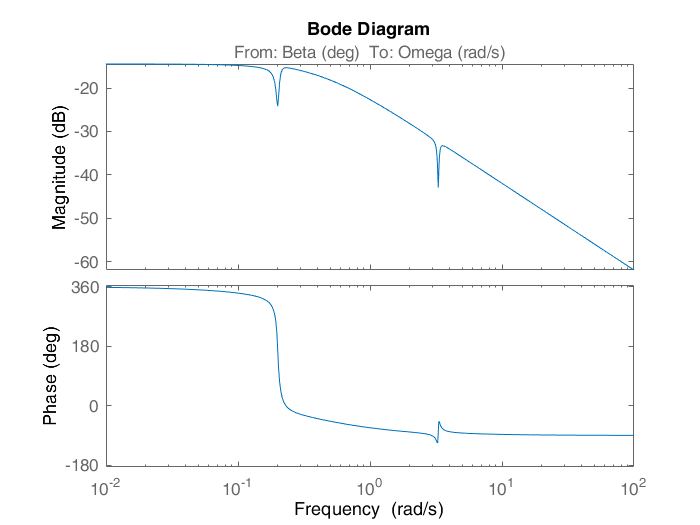

FWT=data.FWT;

A=data.A;
B=data.B;
C=data.C;
D=data.D;
%print(data)
sys1 = ss(A,B,C,D);
%sys2 = ss(A,B1,C2,D2);
bode(-FWT(1,1))

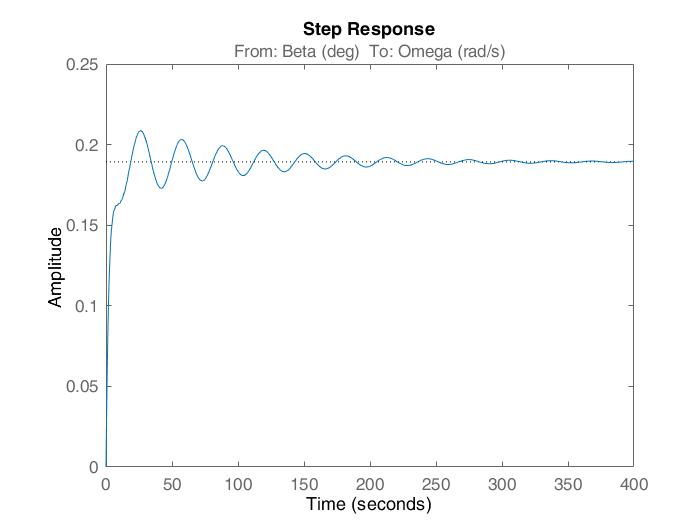

step(-FWT(1,1))

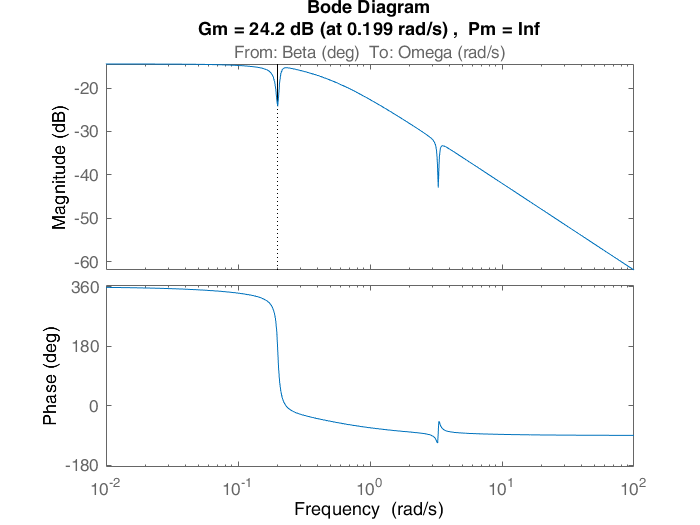

margin(-FWT(1,1))

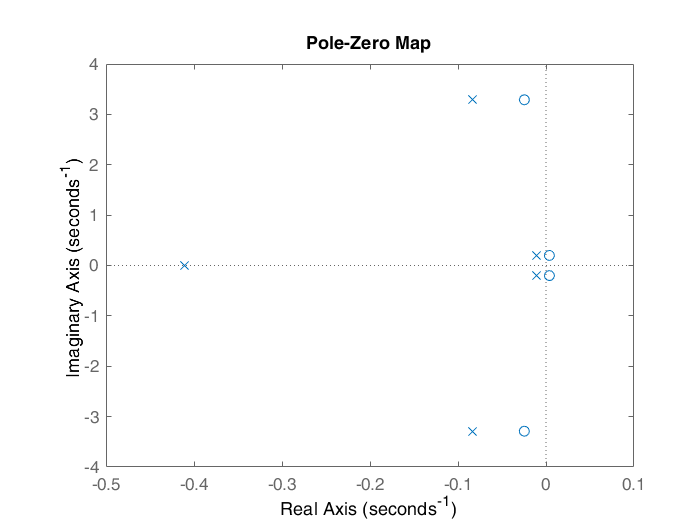

pzmap(-FWT(1,1));

A =zero(-FWT(1,1));
stepinfo(-FWT(1,1))

ans = struct with fields:
        RiseTime: 13.6517
    SettlingTime: 168.7029
     SettlingMin: 0.1704
     SettlingMax: 0.2086
       Overshoot: 10.2142
      Undershoot: 0
            Peak: 0.2086
        PeakTime: 26.4813


s = tf('s');
Plant = -FWT(1,1);
w1=0.2/(2*pi);
w2=3.289/(2*pi);
beta1 = 0.9;
beta2 = 1;
beta3 = 0.9;
beta4 = 1;
C_notch1 = (s^2+w1*beta1*s+w1^2)/(s^2+w1*beta2*s+w1^2)

C_notch1 =
 
  s^2 + 0.02865 s + 0.001013
  --------------------------
  s^2 + 0.03183 s + 0.001013
 
Continuous-time transfer function.



C_notch2 = (s^2+w2*beta3*s+w2^2)/(s^2+w2*beta4*s+w2^2)

C_notch2 =
 
  s^2 + 0.4711 s + 0.274
  ----------------------
  s^2 + 0.5235 s + 0.274
 
Continuous-time transfer function.



Kp = 0.0700

Ki = 0.4500

Kd = 9

Tf = 1

K =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 0.07, Ki = 0.45, Kd = 9, Tf = 1
 
Continuous-time PIDF controller in parallel form.



PoleCancel =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)             ?
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0      -0.03595
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0     -0.003025
   z1 (m)                   0             1             0             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82      -0.01891
   z2 (m)                   0             0             0             1             0             0
   ?                        0             0             0             0             0             0
   ?                        0             0             0             0             0             0
   ?                        0             0             0             0             0             0
   ?                        0             0             0             0       

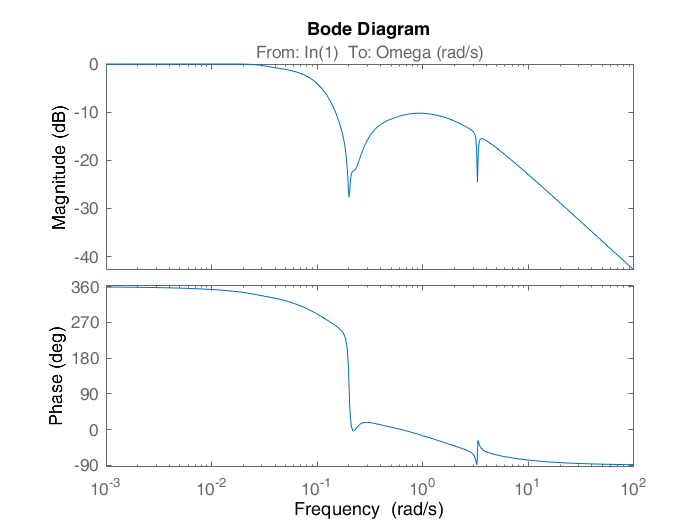

Kp = 0.07

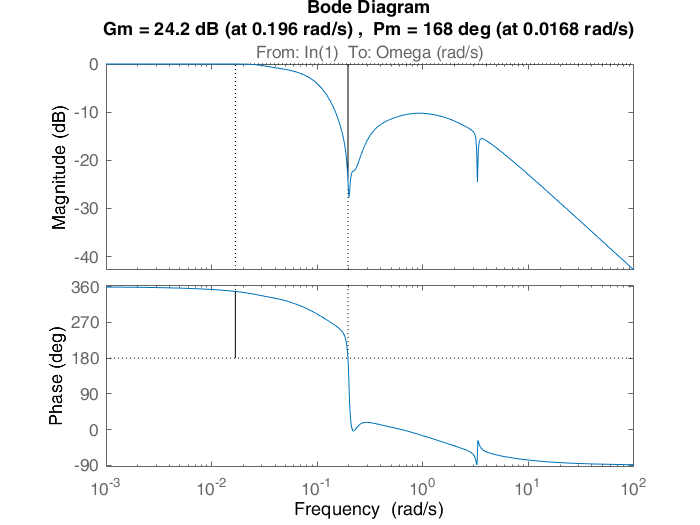

Ki = 0.45
Kd = 9
Tf=1
K = pid(Kp, Ki, Kd, Tf)
PoleCancel = minreal(Plant*K*C_notch1*C_notch2)
sys_cl = feedback(PoleCancel,1);
bode(sys_cl)
margin(sys_cl)

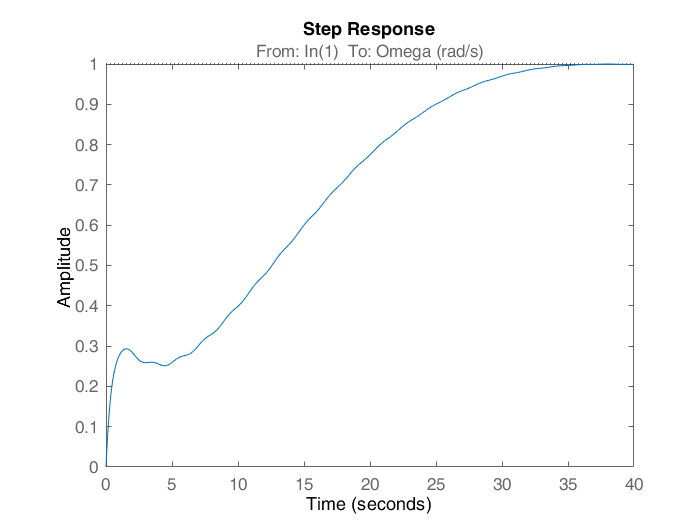

[y,t] = step(sys_cl);
step(sys_cl)

stepinfo(sys_cl)

ans = struct with fields:
        RiseTime: 24.8072
    SettlingTime: 31.3427
     SettlingMin: 0.9005
     SettlingMax: 1.0000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.0000
        PeakTime: 38.0263


sserror=abs(1-y(end))

sserror = 2.0919e-04

fb = bandwidth(sys_cl)

fb = 0.0869